# 1.

clear all
close all
clc

function y = f(x)
    y = x^2;
end

h = 0.1

h = 0.1000


x_1 = -2

x_1 = -2


x = linspace(x_1, 2, 4/h+1)

x =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000



fs = arrayfun(@(u) f(u), x);

fs

fs =     4.0000    3.6100    3.2400    2.8900    2.5600    2.2500    1.9600    1.6900    1.4400    1.2100    1.0000    0.8100    0.6400    0.4900    0.3600    0.2500    0.1600    0.0900    0.0400    0.0100         0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000


# 2.

function y = fp(fs, i, h)
    y = (fs(i+1) - fs(i))/h;
end

fps = zeros(1, length(x));

for i = 1: (length(fs) - 1)
    fps(i) = fp(fs, i, h);
end

# 3.

fps(length(x)) = (fs(end) - fs(end-1))/h

fps =    -3.9000   -3.7000   -3.5000   -3.3000   -3.1000   -2.9000   -2.7000   -2.5000   -2.3000   -2.1000   -1.9000   -1.7000   -1.5000   -1.3000   -1.1000   -0.9000   -0.7000   -0.5000   -0.3000   -0.1000    0.1000    0.3000    0.5000    0.7000    0.9000    1.1000    1.3000    1.5000    1.7000    1.9000    2.1000    2.3000    2.5000    2.7000    2.9000    3.1000    3.3000    3.5000    3.7000    3.9000    3.9000


# 4.

hold on;
plot(fps, x)

# 5.

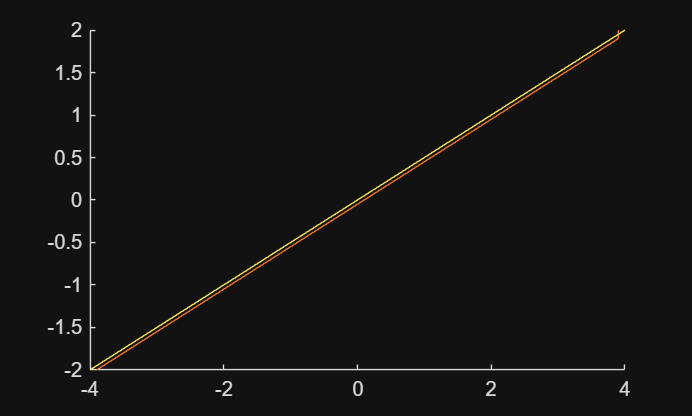

plot(2*x, x)
hold off